## Ejercicio 1

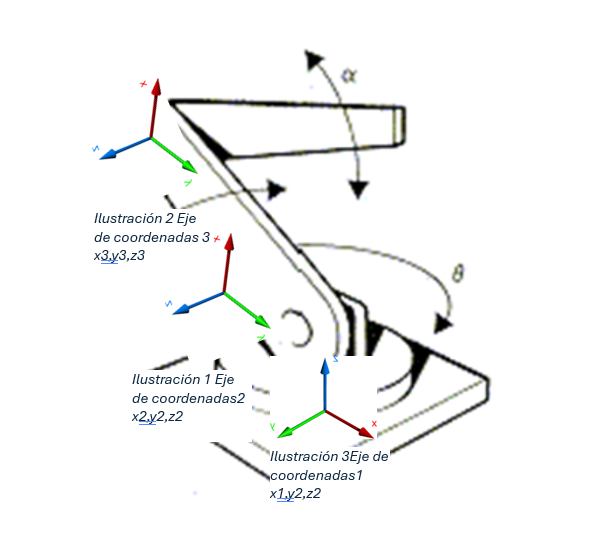

Podemos observar que las articulaciones del robot giran sobre el eje z tal como los paramatros de Denavit-hartenberg dicta. De esta forma necesitamos hacer tres tansformaciones para modelar la cinematica del robot.

%Limpieza de pantalla
clear all

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/        / pi th1(t) \      / pi th1(t) \     \
| 0, -sin| --------- |, -cos| --------- |,  0 |
|        \    180    /      \    180    /     |
|                                             |
|        / pi th1(t) \      / pi th1(t) \     |
| 0,  cos| --------- |, -sin| --------- |,  0 |
|        \    180    /      \    180    /     |
|                                             |
| 1,         0,                 0,         l1 |
|                                             |
\ 0,         0,                 0,          1 /



Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}\,\sigma_{3} & -\sigma_{1}\,\sigma_{4} & -\sigma_{2} & -l_{2}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}\,\sigma_{2} & \sigma_{2}\,\sigma_{4} & -\sigma_{1} & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{2}\\ \sigma_{4} & -\sigma_{3} & 0 & l_{1}+l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ -#1 #3, -#1 #4, -#2,  -l2 #1 sin(th2(t)) \
|                                          |
|  #3 #2,  #2 #4, -#1,  l2 sin(th2(t)) #2  |
|                                          |
|   #4,     -#3,   0,  l1 + l2 cos(th2(t)) |
|                                          |
\    0,      0,    0,           1          /

where

            / pi th1(t) \
   #1 == sin| --------- |
            \    180    /

            / pi th1(t) \
   #2 == cos| --------- |
            \    180    /

            / pi th2(t) \
   #3 == sin| --------- |
            \    180    /

            / pi th2(t) \
   #4 == cos| --------- |
            \    180    /




Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}\,\sigma_{3} & -\sigma_{1}\,\sigma_{4} & -\sigma_{2} & -l_{2}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}\,\sigma_{2} & \sigma_{2}\,\sigma_{4} & -\sigma_{1} & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{2}\\ \sigma_{4} & -\sigma_{3} & 0 & l_{1}+l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{4}\,\sigma_{1} & -\sigma_{4}\,\sigma_{2} & -\sigma_{5} & -\sigma_{4}\,\sigma_{3}\\ \sigma_{1}\,\sigma_{5} & \sigma_{2}\,\sigma_{5} & -\sigma_{4} & \sigma_{5}\,\sigma_{3}\\ \sigma_{2} & -\sigma_{1} & 0 & l_{1}+l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)+\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)+l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)}{180}\right)\\ \sigma_{3}=l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)+\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) \end{array}$$

/ -#4 #1, -#4 #2, -#5,                       -#4 #3                       \
|                                                                         |
|  #1 #5,  #2 #5, -#4,                        #5 #3                       |
|                                                                         |
|                                 /          pi th2(t) \                  |
|   #2,     -#1,   0,  l1 + l3 cos| th3(t) + --------- | + l2 cos(th2(t)) |
|                                 \             180    /                  |
|                                                                         |
\    0,      0,    0,                           1                         /

where

            / pi (th2(t) + th3(t)) \
   #1 == sin| -------------------- |
            \          180         /

            / pi (th2(t) + th3(t)) \
   #2 == cos| -------------------- |
            \          180         /

               /          pi th2(t) \
   #3 == l3 sin| th3(t) + --------- | + l2 sin

Velocidad lineal obtenida mediante el Jacobiano lineal


$$\begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\,\sigma_{4}\,\sigma_{6}-\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sigma_{2}\,\sigma_{5}-l_{3}\,\sigma_{1}\,\sigma_{3}\,\cos\left(\sigma_{7}\right)\\ \sigma_{4}\,\sigma_{2}\,\sigma_{6}-\sigma_{1}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sigma_{5}+l_{3}\,\sigma_{3}\,\cos\left(\sigma_{7}\right)\,\sigma_{2}\\ -\sigma_{4}\,\sigma_{5}-l_{3}\,\sigma_{3}\,\sin\left(\sigma_{7}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{4}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{5}=l_{3}\,\sin\left(\sigma_{7}\right)+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{6}=l_{3}\,\cos\left(\sigma_{7}\right)+l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{7}={\mathrm{th}}_{3}\left(t\right)+\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180} \end{array}$$

Velocidad angular obtenida mediante el Jacobiano angular


$$\left(\begin{array}{c} -\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}\right)$$

close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


Realizamos la primera transformación. La posición de este eje de coordenadas es 0,0,l1 ya que se encuentra en el origen a excepción de z porque esta ligeramente arriba de su base.

Por otro lado ya sabemos que la primera articulación gira en el eje z, y para obtener la matriz de transformación que nos permita ir del sistema 1 a 2, necitamos multriplicarlo por la rotación que nos llevará a dicha nueva configuración de ejes. Analizando la orientación de nuestro eje 1 podemos observar que necesitamos una rotación en y de -90° grados.

%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= rotacion_z(th1)*rotacion_y(-90);

Para este nuevo caso el vector de posición no será fijo, pues depende del movimiento que la articulación tenga dependiente del tiempo. La articulacion rota en el eje z por lo que el movimiento es en los ejes x y, y utilizando las funciones trigonometricas podemos modelar las posiciones que tendrá respecto al tiempo. Por otro lado en este eje ya no necesitamos volver a rotar la matriz de cordenadas. 


%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)=  rotacion_z(th2);

Aquí es el mismo caso que la pagina 2.


%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];

%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=  rotacion_z(th3);

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


Aqui podemos ver las velocidades lineales y angulares obtenidas de los jacobianos. Pudiendo observar que en el caso de las velocidades angulares cada articulación afecta la orientación del efector final es decir de la parte final de la articulación 3.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp');
disp(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp');
disp(W);


%funciones auxiliares para rotaciones
function Rx = rotacion_x(theta)
   
    Rx = [1,         0,           0;
          0, cosd(theta), -sind(theta);
          0, sind(theta),  cosd(theta)];
end


function Ry = rotacion_y(theta)
    % ROTACION_Y - Matriz de rotación alrededor del eje Y
    Ry = [ cosd(theta), 0, sind(theta);
                  0, 1,          0;
          -sind(theta), 0, cosd(theta)];
end

function Rz = rotacion_z(theta)
    % ROTACION_Z - Matriz de rotación alrededor del eje Z
    Rz = [cosd(theta), -sind(theta), 0;
          sind(theta),  cosd(theta), 0;
                 0,            0, 1];
end
